# **Build a Monte Carlo Simulation **

**Construct Synthetic Data**

numVariables = 5; % Number of random variables
numSamples = 1000; % Number of samples

**Generate random volatility forecasts (positive values)**

volatilityForecasts = rand(1, numVariables) * 0.5 + 0.1; % Example range: [0.1, 0.6]

**Generate random correlation matrix**

correlationMatrix = rand(numVariables);
correlationMatrix = correlationMatrix + correlationMatrix'; % Make symmetric
correlationMatrix(1:numVariables+1:end) = 1; % Diagonal elements to 1
correlationMatrix = correlationMatrix / max(abs(eig(correlationMatrix))); % Ensure spectral radius <= 1

**Generate random data based on volatility forecasts and correlation matrix**

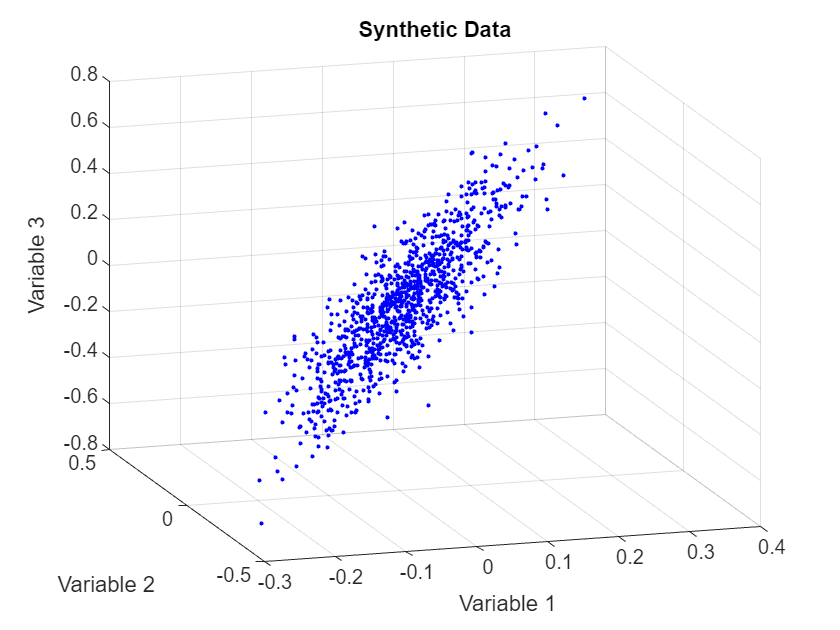

data = mvnrnd(zeros(1, numVariables), constructCovariance(volatilityForecasts, correlationMatrix), numSamples);

% Plot the data for visualization (optional)
figure;
scatter3(data(:,1), data(:,2), data(:,3), 'b.');
xlabel('Variable 1');
ylabel('Variable 2');
zlabel('Variable 3');
title('Synthetic Data');

**Test the constructCovariance function**

covMatrix = constructCovariance(volatilityForecasts, correlationMatrix);
disp('Constructed Covariance Matrix:');

Constructed Covariance Matrix:


disp(covMatrix);

    0.0090    0.0101    0.0166    0.0165    0.0209
    0.0101    0.0171    0.0225    0.0304    0.0197
    0.0166    0.0225    0.0345    0.0425    0.0318
    0.0165    0.0304    0.0425    0.0672    0.0180
    0.0209    0.0197    0.0318    0.0180    0.0635

